function J = ftp_fuel_objective(x)
    T_em_thresh   = x(1);
    Q_low  = x(2);
    Q_max = x(3);

    assignin('base','T_em_thresh',T_em_thresh);
    assignin('base','Q_low',Q_low);
    assignin('base','Q_max',Q_max);
    
    qss_example = 'qss_hybrid_electric_vehicle_S_H.mdl';
    
    out = sim(qss_example,'StopTime','1877','SaveOutput','on','SaveTime','on');
    fuel_l  = out.get('V_CE_equiv');      % total litres
    Q_final = out.get('Q_BT');      % Coulombs
    Q0   = evalin('base','Q_BT0');
    soc  = Q_final / Q0;
    pen  = 0;
    if soc < 0.20, pen = 10*(0.20 - soc); end % was 30 
    if soc > 0.95, pen = 10*(soc - 0.95); end % was 90

    % Objective = fuel + penalty (lower is better)
    J = fuel_l + pen;
    J= J(end);
    
end

initialxx= [35 , 0.3 , 0.99]

initialxx =    35.0000    0.3000    0.9900


Lower_bounds =[20 , 0.2 , 0.70]

Lower_bounds =    20.0000    0.2000    0.7000


Upper_bounds=[60 , 0.4 , 0.95]

Upper_bounds =    60.0000    0.4000    0.9500


Q_BT0= 18000;

Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.



                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       4    3.358972e+00    0.000e+00    0.000e+00

Initial point is a local minimum that satisfies the constraints.

Optimization completed because at the initial point, the objective function is non-decreasing 
in feasible directions to within the value of the optimality tolerance, and 
constraints are satisfied to within the value of the constraint tolerance.

<

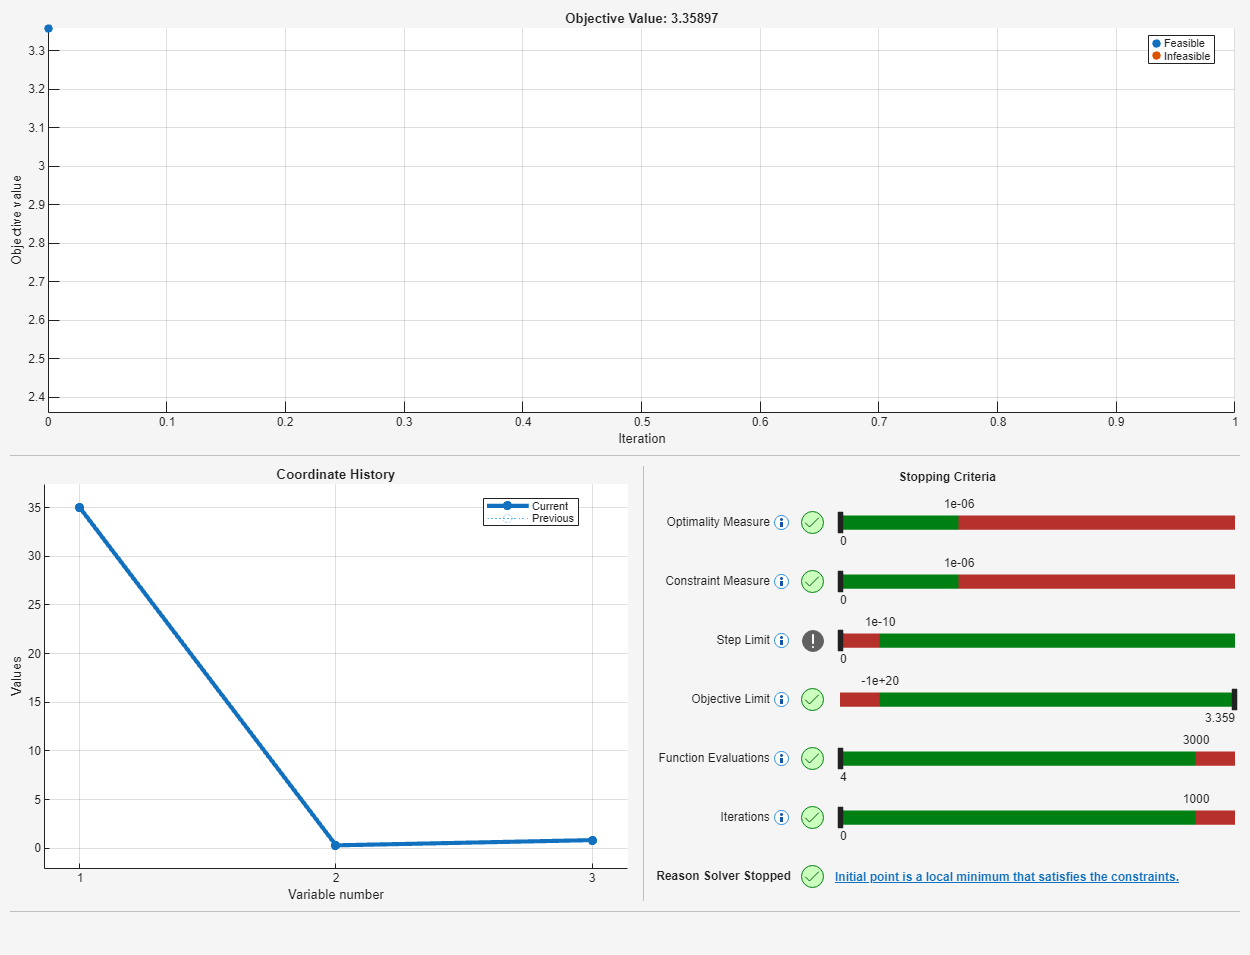

% Set nondefault solver options
options = optimoptions("fmincon","Display","iter","PlotFcn","optimplot");

% Solve
[solution,objectiveValue] = fmincon(@ftp_fuel_objective,initialxx,[],[],[],...
    [],Lower_bounds,Upper_bounds,[],options);


% Clear variables
clearvars options